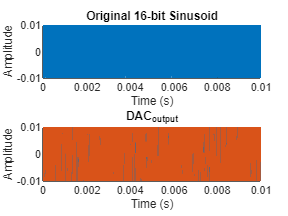

clear all;
close all;

% Parameters
fs = 50e6;          % Sampling frequency in Hz
f_sin = 100e3;        % Sinusoid frequency in Hz
t = 0:1/fs:10e-3;        % Time vector


% Generate 16-bit fixed-point sinusoid
A = 1;               % Amplitude
output_amplitude = 0.01; %Signal output amplitude[V]
phi = 0;             % Phase
sinusoid = A * sin(2 * pi * f_sin * t + phi);
cosinusoid = A * cos(2 * pi * f_sin * t + phi);

% Quantize to 16 bits
bits = 16;
quantized_sinusoid = fi(sinusoid, 1, bits, bits-1);
quantized_cosinusoid = fi(cosinusoid, 1, bits, bits-1);

% Multiply for DAC scaling factor
DAC_scale = 2.5;
actual_wfm_amplitude = fi(output_amplitude/2.5,0,17,16); %Format Q1.16 for multiplication (unsigned)

multiplication = fimath('OverflowAction','Saturate','RoundingMethod','Floor', ...
    'ProductMode','SpecifyPrecision','ProductWordLength',16,'ProductFractionLength',15);

actual_wfm_amplitude.fimath = multiplication;
quantized_sinusoid.fimath = multiplication;

quantized_scaled_sinuosid = quantized_sinusoid * actual_wfm_amplitude;

% Downsample by a factor of 35
downsample_factor = 35;
quantized_downsampled_sinusoid = downsample(quantized_scaled_sinuosid, downsample_factor);

% Upsample to original number of samples using zero-order hold
upsample_factor = downsample_factor;
upsampled_sinusoid = interp1((1:length(quantized_downsampled_sinusoid))*upsample_factor, double(quantized_downsampled_sinusoid), 1:length(quantized_sinusoid), 'next');
upsampled_sinusoid(isnan(upsampled_sinusoid)) = 0;

% % Quantize to 14 bits
% quantized_upsampled_sinusoid = quantize(quantizer('RoundMode','floor','Format',[14,13]),upsampled_sinusoid);
% DAC_output = double(quantized_upsampled_sinusoid(1:length(quantized_scaled_sinuosid)))*DAC_scale;
% Output at 16 bits
quantized_upsampled_sinusoid = upsampled_sinusoid;
DAC_output = double(quantized_upsampled_sinusoid(1:length(quantized_scaled_sinuosid)))*DAC_scale;
% Plot the results
figure();
subplot(2,1,1);
hold on
plot(t, double(quantized_scaled_sinuosid)*DAC_scale, 'LineWidth', 2);
title('Original 16-bit Sinusoid');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, double(quantized_scaled_sinuosid)*DAC_scale, 'LineWidth', 2);
hold on;
plot(t, DAC_output, 'LineWidth', 2);
title('DAC_output');
xlabel('Time (s)');
ylabel('Amplitude');

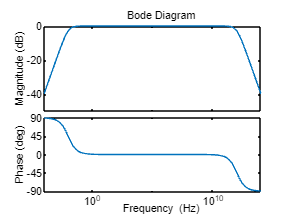


% Define a continuous transfer function (example)
G = 1;
Q = 0.0000001;
Fc = f_sin;
%Fc = 330e3;
Wc = 2*pi*Fc;
numerator = G * [1 0];
denominator = [Q/Wc 1 Q*Wc];
H = tf(numerator,denominator);
figure();
P = bodeoptions;
P.FreqUnits = 'Hz';
bodeplot(H,P);

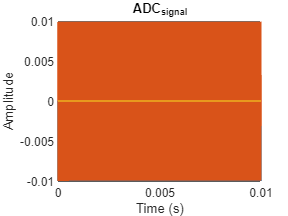


% Convert to discrete-time transfer function with the new sampling rate
Ts = 1 / (fs / downsample_factor * upsample_factor);  % New sampling time
sys_d = c2d(tf(numerator, denominator), Ts);



% Simulate the quantized upsampled sinusoid through the discrete-time transfer function
Membrane_signal = lsim(sys_d, double(DAC_output), t)';

% Noise generation
noise_density = 10e-9;     % 10 nV/sqrt(Hz) noise spectral density
noise_density = 0;     % 10 nV/sqrt(Hz) noise spectral density
noise_std_dev = noise_density * sqrt(fs);
white_noise = randn(1, length(DAC_output)) * noise_std_dev;

%ADC acquisition
ADC_signal_cont = Membrane_signal + white_noise;

%FOR TEST PURPOSE; REMOVE OTHERWISE
%ADC_signal_cont = double(DAC_output) + white_noise;;

ADC_signal = fi(ADC_signal_cont, 1, bits, bits-1);

% Plot the results
figure();
plot(t, ADC_signal_cont);
hold on
plot(t, ADC_signal);
plot(t, white_noise)
title('ADC_signal');
xlabel('Time (s)');
ylabel('Amplitude');

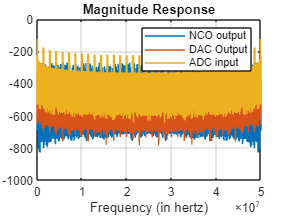

% FFT TIME %
N = length(sinusoid);
w = blackman(N)';
dF = fs/N;
f = 0:dF:fs-dF;

fft_ADC_signal_cont = fft(ADC_signal_cont.*w);
fft_ADC_signal_disc = fft(double(ADC_signal).*w);
fft_DAC_output = fft(DAC_output.*w);
fft_quantized_scaled_sinuosid = fft(double(quantized_scaled_sinuosid).*w*DAC_scale);

figure()
plot(f,20*log(abs(fft_quantized_scaled_sinuosid)/N));
hold on
plot(f,20*log(abs(fft_DAC_output)/N));
plot(f,20*log(abs(fft_ADC_signal_disc)/N));
%plot(f,20*log(abs(fft_ADC_signal_cont)/N));
legend('NCO output','DAC Output', 'ADC input')
grid on
xlabel('Frequency (in hertz)');
title('Magnitude Response');

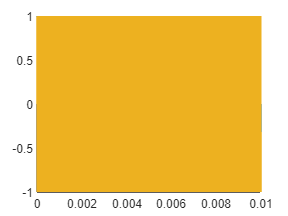

%DEMODULATION
figure()
plot(t,sinusoid);
hold on
plot(t, DAC_output);
plot(t,ADC_signal/double(max(ADC_signal)));

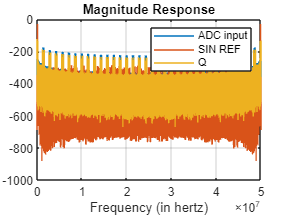


%Input multiplication with 32 bit output, Floor rounding and saturation
%If the output is reduced 
input_multiplication_out_bits = 32;
input_multiplication = fimath('ProductMode','FullPrecision');


ADC_signal.fimath = input_multiplication;
quantized_cosinusoid.fimath = input_multiplication;
quantized_sinusoid.fimath = input_multiplication;

Q = ADC_signal .* quantized_sinusoid;
I = ADC_signal .* quantized_cosinusoid;


fft_quantized_sinusoid = fft(double(quantized_sinusoid).*w);
fft_Q = fft(double(Q).*w);
fft_I = fft(double(I).*w);
fft_cmp = fft((double(I)+j*double(Q)).*w);


figure()
plot(f,20*log(abs(fft_ADC_signal_disc)/N));
hold on
plot(f,20*log(abs(fft_quantized_sinusoid)/N));
plot(f,20*log(abs(fft_Q)/N));
legend('ADC input','SIN REF', 'Q')
grid on
xlabel('Frequency (in hertz)');
title('Magnitude Response');

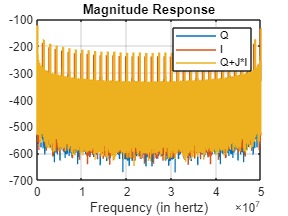



figure()
plot(f,20*log(abs(fft_Q)/N));
grid on
hold on
plot(f,20*log(abs(fft_I)/N));
plot(f,20*log(abs(fft_cmp)/N));
legend('Q','I','Q+J*I');
xlabel('Frequency (in hertz)');
title('Magnitude Response');

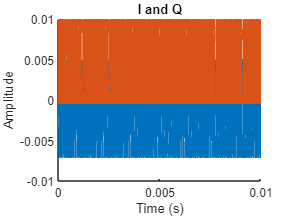


figure()
%plot(t, ADC_signal, 'LineWidth', 1);
hold on;
plot(t, I, 'LineWidth', 1);
plot(t, Q, 'LineWidth', 1);
title('I and Q');
xlabel('Time (s)');
ylabel('Amplitude');


I_filt = mean(double(I));
Q_filt = mean(double(Q));

output = Q_filt + j*I_filt;
output = 2 * output; %this is needed since half the signal is lost while demodulating
amplitude = abs(output)

amplitude = 0.0099

phase = angle(output)*180/pi

phase = -12.9561

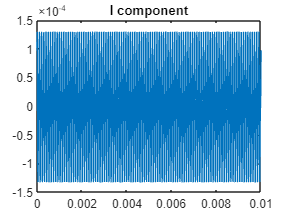

%IDEAL FILTER%

%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
%wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
%fc=wc/(2*pi)*fs
%tau=1/(2*pi*fc)
Time_per_step = 0.01;
samples_per_step = fs*Time_per_step;
tau = Time_per_step/6.91; %for 99.9% settling of first order filter
fc = 1/(2*pi*tau);
wc = fc/fs * 2 * pi;
alpha = 1-(1-sin(wc))/cos(wc);
%alpha = 2^-26

tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
fvtool(tustin_iir,'Fs',fs);

I_tustin = tustin_iir(double(I'))';
reset(tustin_iir)
Q_tustin = tustin_iir(double(Q'))';

figure()
plot(t, double(I));
title('I component');

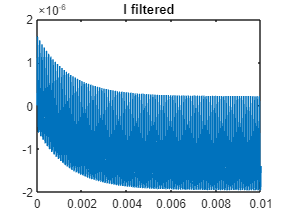

figure()
plot(t, I_tustin);
title('I filtered');

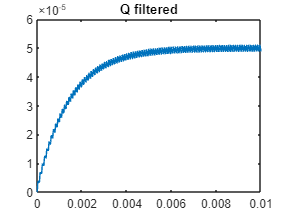

figure()
plot(t, Q_tustin);
title('Q filtered');


output_tustin = Q_tustin(end) + j*I_tustin(end);
output_tustin = 2 * output_tustin;
amplitude = abs(output_tustin)

amplitude = 9.7641e-05

phase = angle(output_tustin)*180/pi

phase = -1.6422

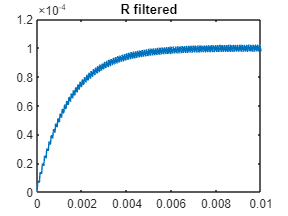


output_tustin_temp = 2*Q_tustin + 2*j*I_tustin;
figure()
plot(t, abs(output_tustin_temp));
title('R filtered')

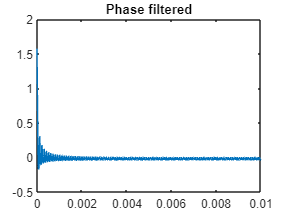

figure()
plot(t, angle(output_tustin_temp));
title('Phase filtered')


steps = output_tustin_temp(samples_per_step:samples_per_step:end)

steps = 9.7602e-05 - 2.8010e-06i

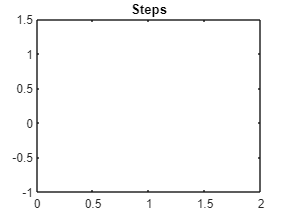

figure()
plot(abs(steps));
title('Steps')

% Compare IIRfilter with the implemented for function%
% 
% Q_tustin_function = tustin_ideal(double(Q),alpha);
% Q_tustin_function = tustin_ideal(double(Q),alpha);
% figure()
% plot(t, Q_tustin-Q_tustin_function);

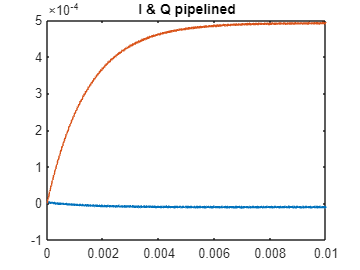

% Compare IIRfilter with the implemented pipelined for function%

[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipelined(double(Q), double(I), alpha);
figure()
plot(t, I_tustin_pipelined);
hold on;
plot(t, Q_tustin_pipelined);
title('I & Q pipelined');

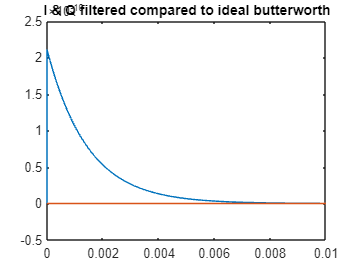

figure()
plot(t, [0, I_tustin(1:end-1)]-I_tustin_pipelined);
hold on;
plot(t, Q_tustin-Q_tustin_pipelined);
title('I & Q filtered compared to ideal butterworth');


% Calculate phase and amplitude
output_tustin_pipelined = Q_tustin_pipelined(end) + j*I_tustin_pipelined(end);
output_tustin_pipelined = 2 * output_tustin_pipelined;
amplitude_pipelined = abs(output_tustin_pipelined)

amplitude_pipelined = 9.8355e-04

phase_pipelined = angle(output_tustin_pipelined)*180/pi

phase_pipelined = -1.5299

% Compare IIRfilter with the implemented fixed point pipelined for function%

[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipelined_fp(Q, I, alpha);
figure()
plot(t, I_tustin_pipelined);
hold on;
plot(t, Q_tustin_pipelined);
title('I & Q fixed point');
figure()
plot(t, [0, I_tustin(1:end-1)]-I_tustin_pipelined);
hold on;
plot(t, Q_tustin-Q_tustin_pipelined);
title('I & Q filtered compared to ideal butterworth');

% Calculate phase and amplitude
output_tustin_pipelined = double(Q_tustin_pipelined(end)) + j*double(I_tustin_pipelined(end));
output_tustin_pipelined = 2 * output_tustin_pipelined;
amplitude_pipelined = abs(output_tustin_pipelined)
phase_pipelined = angle(output_tustin_pipelined)*180/pi

output_tustin_temp = 2*Q_tustin_pipelined + 2*j*I_tustin_pipelined;
figure()
plot(t, abs(output_tustin_temp));
title('R filtered')
figure()
plot(t, abs(output_tustin_temp));
title('Phase filtered')

steps = output_tustin_temp(samples_per_step:samples_per_step:end)
figure()
plot(abs(steps));
title('Steps')

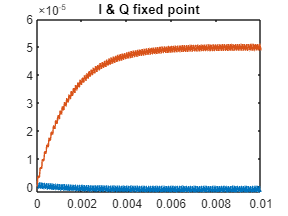

% Compare IIRfilter with the implemented fixed point with late multiply pipelined for function% 
% This is the version implemented in fpga

[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipeline_fp_opt(Q, I, alpha);
figure()
plot(t, I_tustin_pipelined);
hold on;
plot(t, Q_tustin_pipelined);
title('I & Q fixed point');

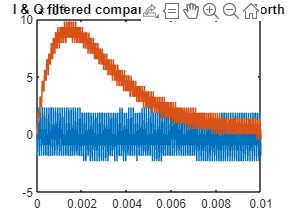

figure()
plot(t, [0, I_tustin(1:end-1)]-I_tustin_pipelined);
hold on;
plot(t, Q_tustin-Q_tustin_pipelined);
title('I & Q filtered compared to ideal butterworth');


% Calculate phase and amplitude
output_tustin_pipelined = double(Q_tustin_pipelined(end)) + j*double(I_tustin_pipelined(end));
output_tustin_pipelined = 2 * output_tustin_pipelined;
amplitude_pipelined = abs(output_tustin_pipelined)

amplitude_pipelined = 9.7641e-05

phase_pipelined = angle(output_tustin_pipelined)*180/pi

phase_pipelined = -1.6419

% Pass the data to the testbench
% Generate 2 MHz sinusoid

disp(['Da mettere nella testBench per alpha: ', fi([alpha],1,27,26).bin])

Da mettere nella testBench per alpha: 000000000000000001110011111


I_short = fi(I,1,26,25,fimath('RoundingMethod','Floor'));
Q_short = fi(Q,1,26,25,fimath('RoundingMethod','Floor'));
I_dec = int32(double(I_short)*2^25);
Q_dec = int32(double(Q_short)*2^25);

% Write to text files
writematrix(I_dec', 'I.txt', 'Delimiter', '\t');
writematrix(Q_dec', 'Q.txt', 'Delimiter', '\t');
writematrix(dec2bin(I_dec'), 'I_bin.txt', 'Delimiter', '\t');
writematrix(dec2bin(Q_dec'), 'Q_bin.txt', 'Delimiter', '\t');

% get the filter result
I_tb_lpf = double(typecast(uint32(readmatrix("I_lpf.txt", 'Delimiter', '\t')), 'int32')')*2^-31;
Q_tb_lpf = double(typecast(uint32(readmatrix("I_lpf.txt", 'Delimiter', '\t')), 'int32')')*2^-31;

figure();
plot (t(1:end-1), [I_tustin_pipelined(1:end-1)])
hold on
plot (t(1:end-1), [0, I_tb_lpf])
plot (t(1:end-1), [Q_tustin_pipelined(1:end-1)])
plot (t(1:end-1), [0, Q_tb_lpf])

max(double([I_tustin_pipelined(1:end-1)]) - double([0, I_tb_lpf]))

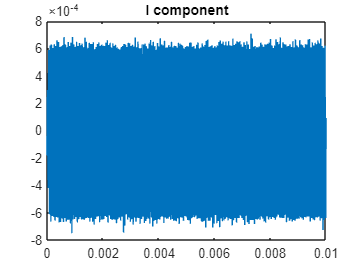

%IDEAL order 2 FILTER%

%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
%wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
%fc=wc/(2*pi)*fs
%tau=1/(2*pi*fc)
Time_per_step = 0.01;
samples_per_step = fs*Time_per_step;
tau = Time_per_step/9.23; %for 99.9% settling of second order filter
fc = 1/(2*pi*tau);
wc = fc/fs * 2 * pi;
alpha = 1-(1-sin(wc))/cos(wc);
%alpha = 2^-26

tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
%fvtool(tustin_iir,'Fs',fs);

I_tustin = tustin_iir(double(I'))';
reset(tustin_iir) 
Q_tustin = tustin_iir(double(Q'))';
reset(tustin_iir)
I_tustin = tustin_iir(double(I_tustin'))';
reset(tustin_iir)
Q_tustin = tustin_iir(double(Q_tustin'))';


figure()
plot(t, double(I));
title('I component');

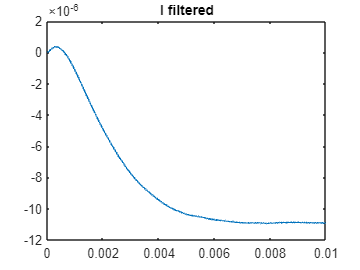

figure()
plot(t, I_tustin);
title('I filtered');

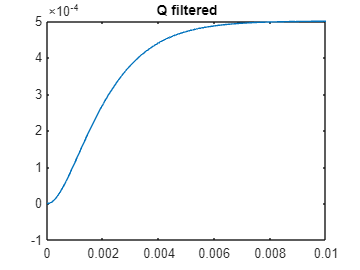

figure()
plot(t, Q_tustin);
title('Q filtered');


output_tustin = Q_tustin(end) + j*I_tustin(end);
output_tustin = 2 * output_tustin;
amplitude = abs(output_tustin)

amplitude = 9.9900e-04

phase = angle(output_tustin)*180/pi

phase = -1.2521

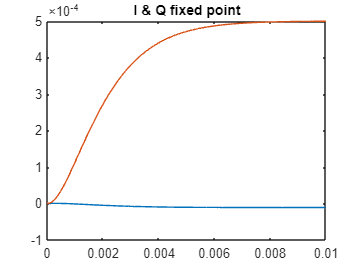

% 2 order IIR filter for possible FPGA implementation
[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipeline_fp_opt(Q, I, alpha);
[Q_tustin_pipelined, I_tustin_pipelined]  = tustin_pipeline_fp_opt(Q_tustin_pipelined, I_tustin_pipelined, alpha);
figure()
plot(t, I_tustin_pipelined);
hold on;
plot(t, Q_tustin_pipelined);
title('I & Q fixed point');

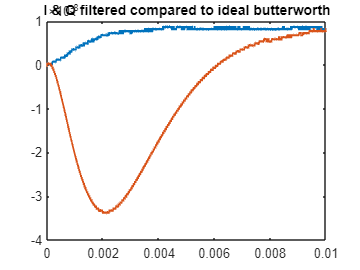

figure()
plot(t, [0, I_tustin(1:end-1)]-I_tustin_pipelined);
hold on;
plot(t, Q_tustin-Q_tustin_pipelined);
title('I & Q filtered compared to ideal butterworth');


% Calculate phase and amplitude
output_tustin_pipelined = double(Q_tustin_pipelined(end)) + j*double(I_tustin_pipelined(end));
output_tustin_pipelined = 2 * output_tustin_pipelined;
amplitude_pipelined = abs(output_tustin_pipelined)

amplitude_pipelined = 9.9899e-04

phase_pipelined = angle(output_tustin_pipelined)*180/pi

phase_pipelined = -1.2531